# **Effet d'une arthroplastie totale inversée d'épaule sur les synergies musculaires**

**Analyse synergies sujet par sujet pour les 4 mouvements fonctionnels (concaténés)**

Traitement du mouvement fonctionnel 1: Porter les mains à la bouche


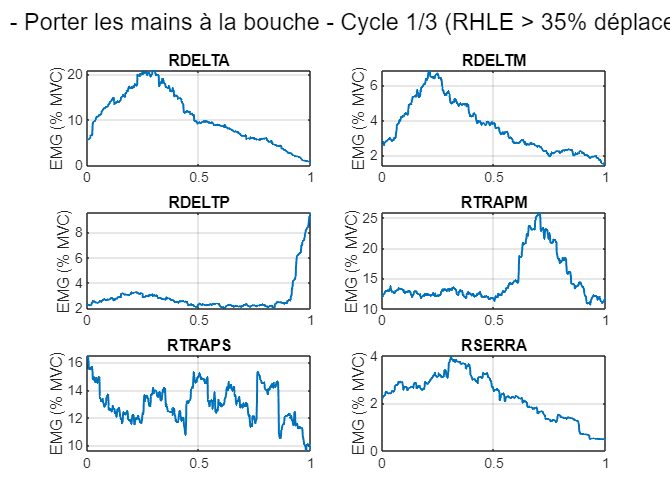

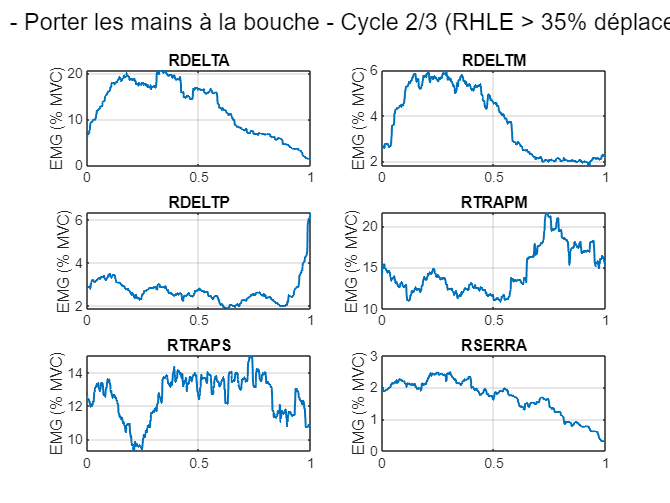

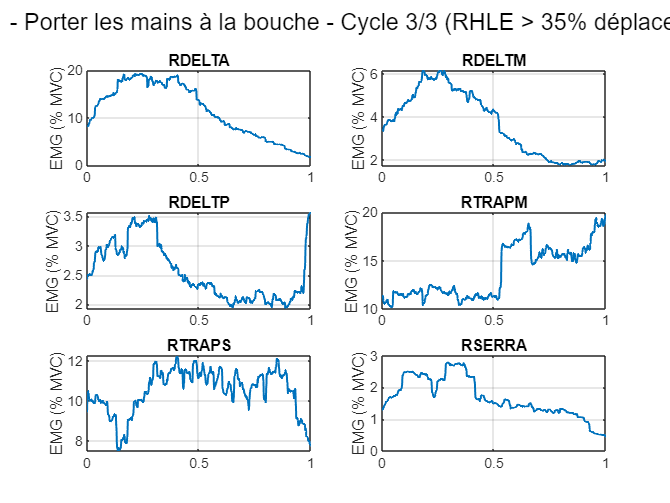

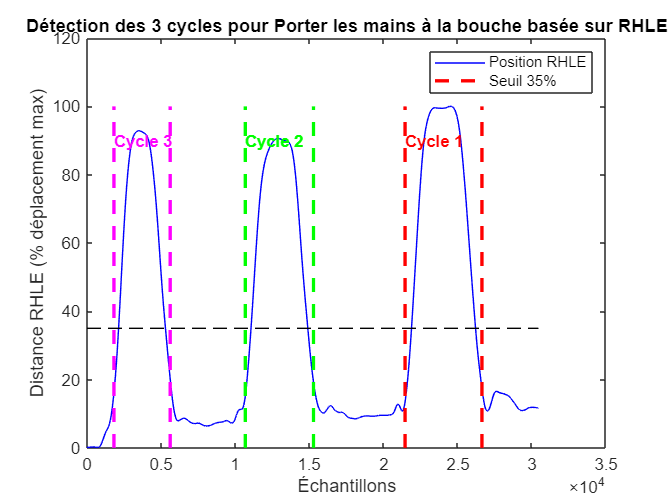

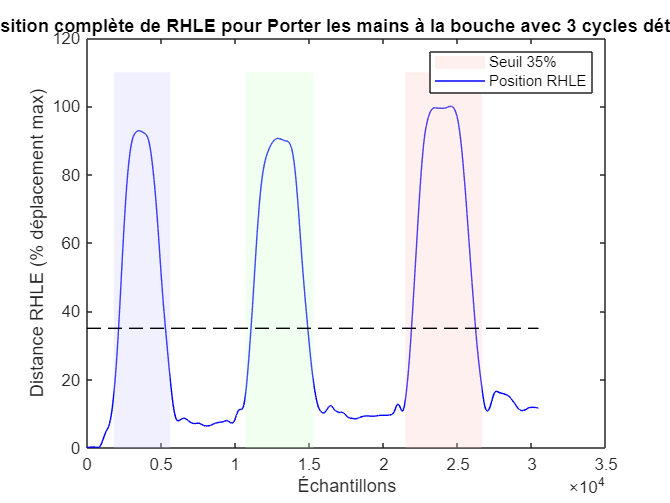

Traitement du mouvement fonctionnel 2: Toucher le haut de la tête


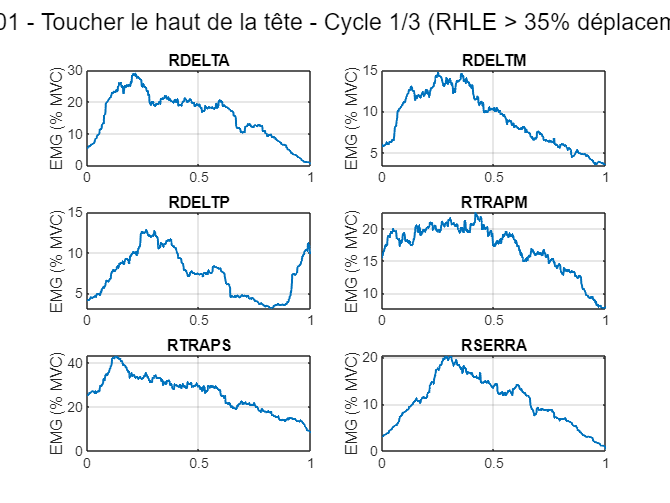

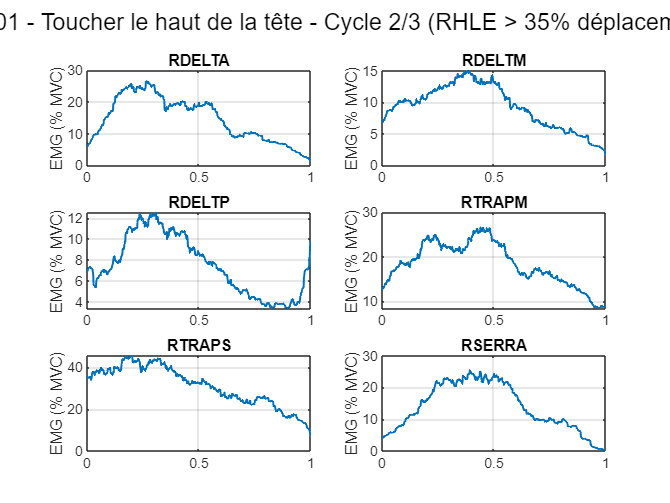

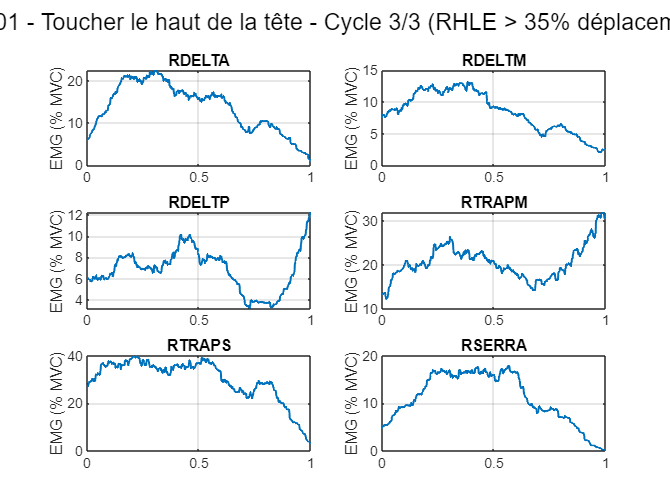

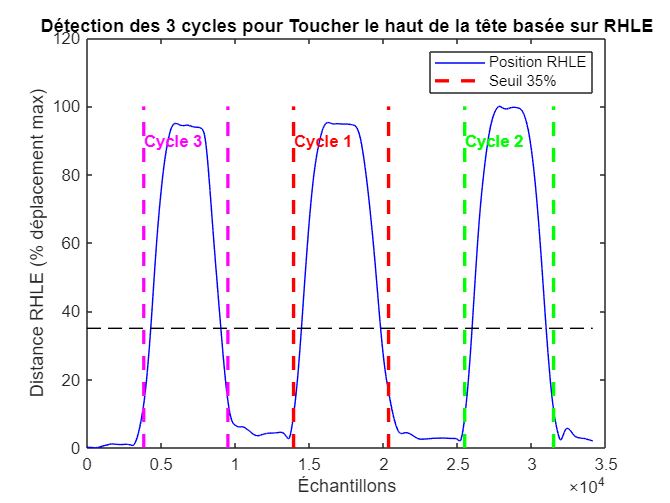

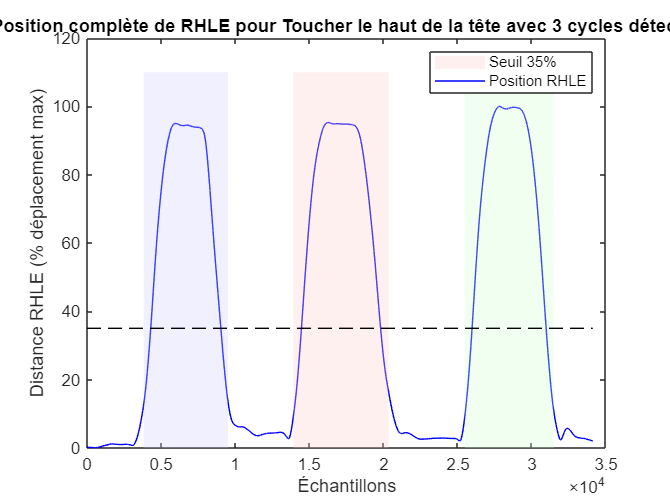

Traitement du mouvement fonctionnel 3: Porter les mains le plus haut possible au-dessus de la tête


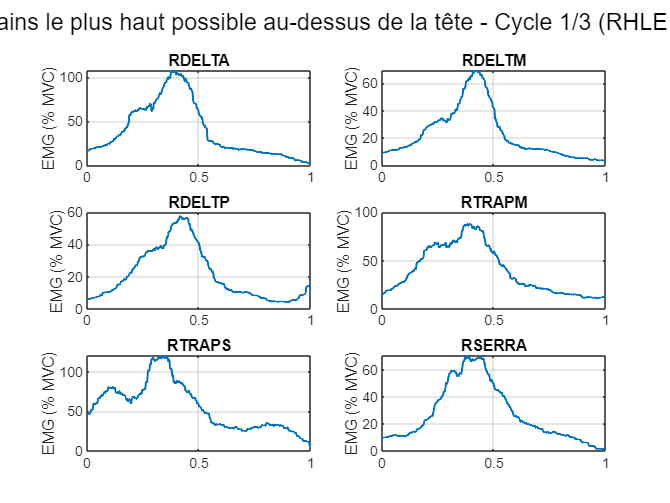

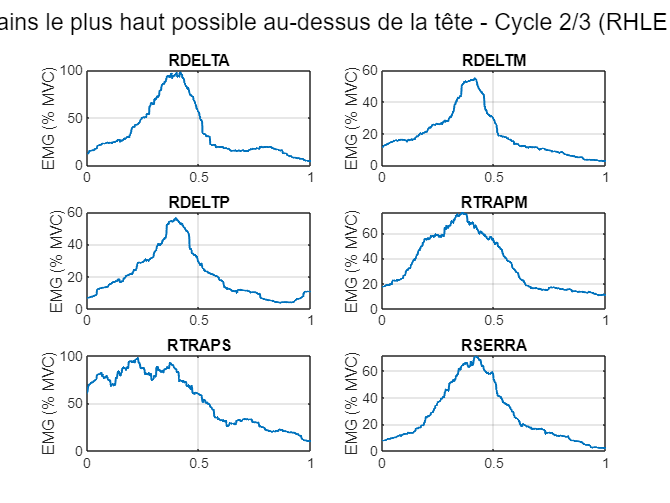

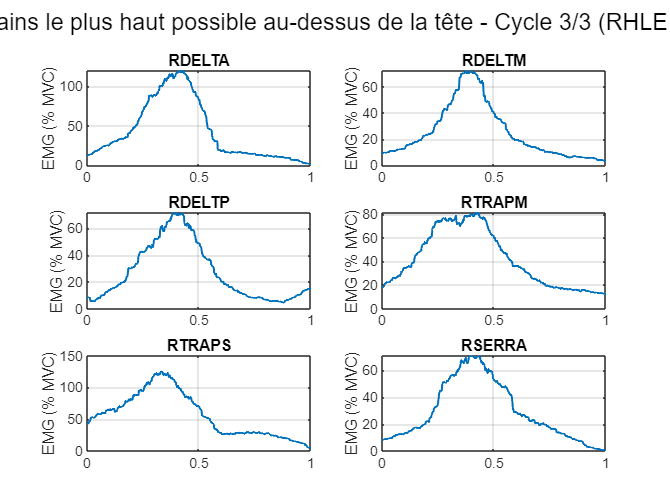

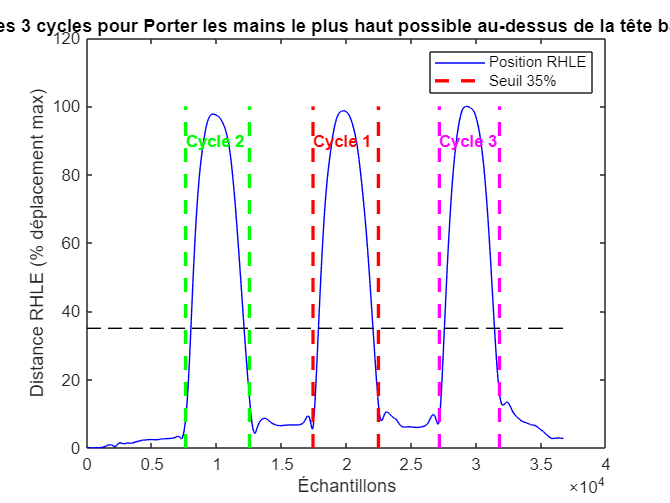

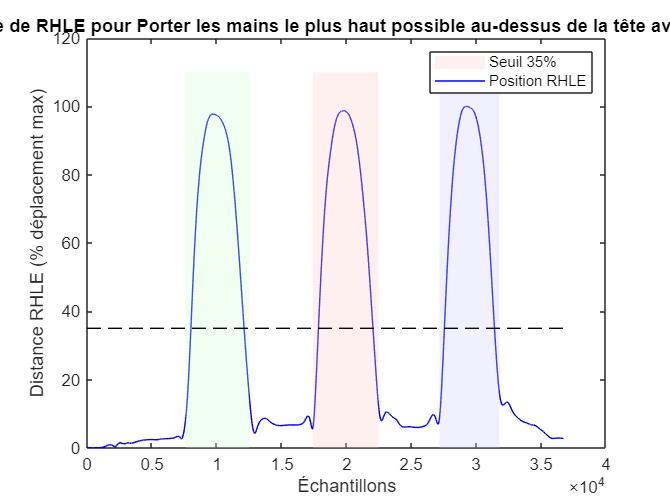

Traitement du mouvement fonctionnel 4: Porter les mains le plus haut possible le long de la colonne vertébrale


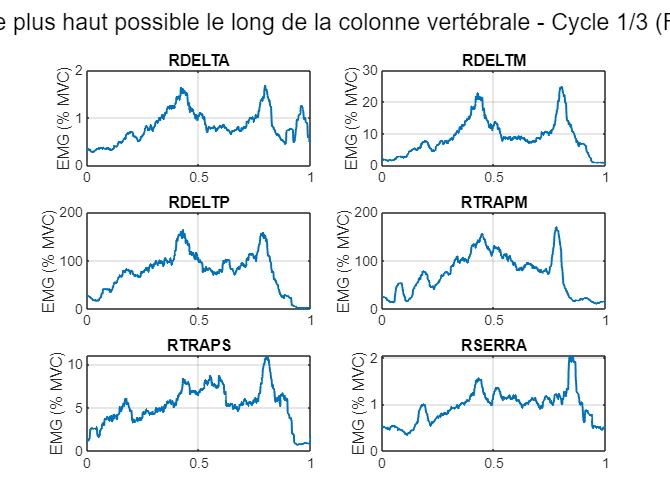

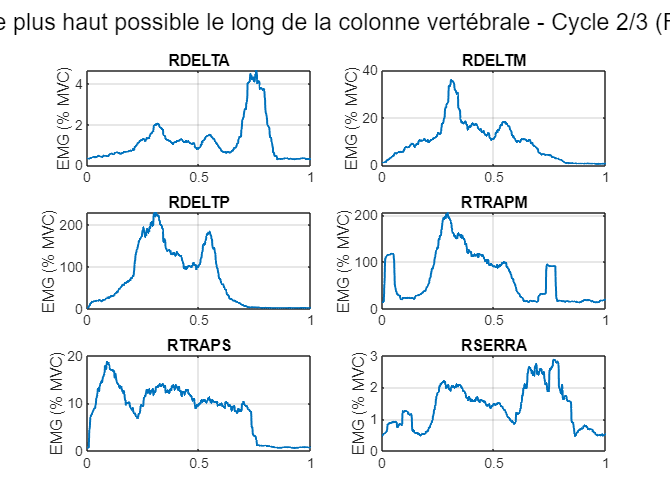

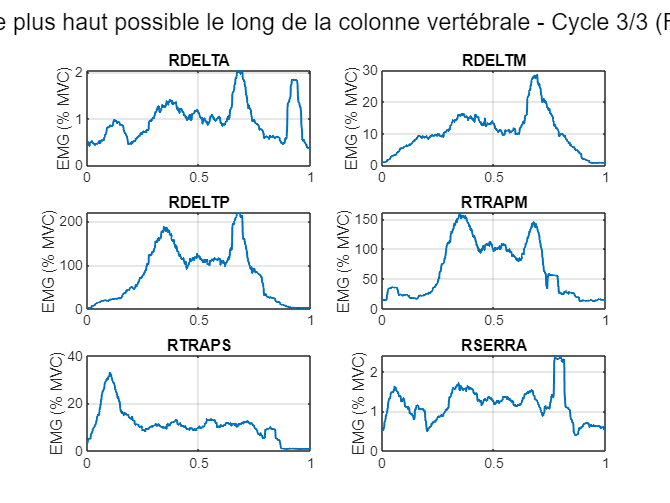

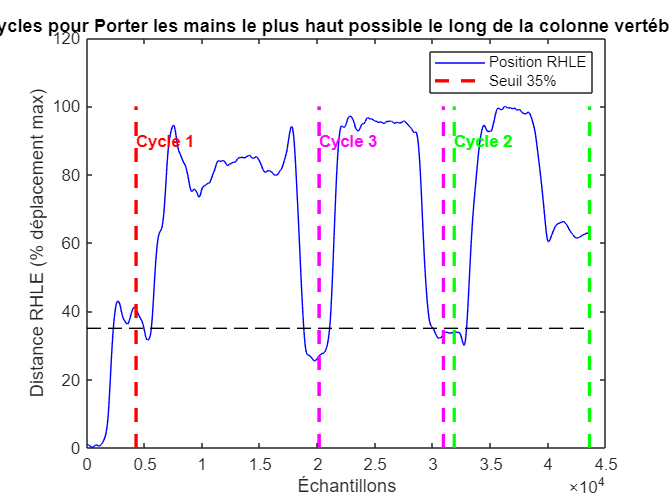

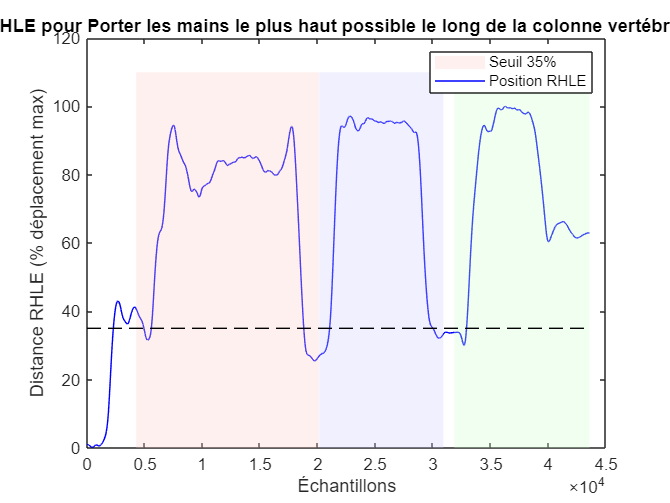

clc, clear all; 

% Ajout de la bibliothèque btk
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

% Définition sujet 
subjects = {'MG20'}; % Marche pour un sujet

% 'MF01', 'TF02', 'YL03','SC04', 'RF05', 'AP06'
% 'TD07', 'IS08', 'LC09', 'MP10', 'PK11'
% 'TF12','JM13', 'GD14', 'LD15', 'LM16','NQ17', 'JV18'
% 'EG19', 'MG20', 'LB21', 'AP22', 'SC23'
% 'TM24', 'EG25', 'RL26'
nb_subjects = length(subjects);

% Définition des muscles (choisir droite ou gauche)
muscles = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPM', 'RTRAPS', 'RSERRA'};
% muscles = {'LDELTA', 'LDELTM', 'LDELTP', 'LTRAPM', 'LTRAPS', 'LSERRA'};
nb_muscles = length(muscles);

% Définition des labels pour les tâches
functional_labels = {...
    'Porter les mains à la bouche', ...
    'Toucher le haut de la tête', ...
    'Porter les mains le plus haut possible au-dessus de la tête', ...
    'Porter les mains le plus haut possible le long de la colonne vertébrale'};
analytic_labels = { 
    'Flexion (élévation sagittale)', ...
    'Abduction (élévation coronale)', ...
    'Rotation externe (abduction 0°)', ...
    'Rotation interne (abduction 0°)'};

nb_functional = length(functional_labels);
nb_analytic = length(analytic_labels);

% Paramètres EMG
fs = 2000;
[b, a] = butter(4, [15, 475] / (fs/2), 'bandpass');
rms_window = round(0.250 * fs);
num_points = 1000;
time_normalized = linspace(0, 1, num_points);

% Paramètres pour la détection basée sur le marqueur RHLE
position_threshold_percent = 35; % 15  % Seuil de déplacement significatif (% du déplacement max)
min_duration = 0.1;  % Durée minimale d'un mouvement (en secondes)
num_cycles = 3;      % Nombre de cycles à traiter par mouvement fonctionnel

% Association Muscle -> Tâche Analytique définie manuellement
assigned_analytics = [1, 2, 2, 2, 2, 2]; %4

% Initialisation des MVC des tâches analytiques
mvc = zeros(nb_muscles, 1);
all_functional_data = cell(nb_subjects, nb_functional, nb_muscles, num_cycles);
% Remplacez cette partie:
num_available_cycles_per_functional = zeros(nb_functional, 1);

% Calcul du MVC basé sur la tâche analytique assignée
for subj_idx = 1:nb_subjects
    for m = 1:nb_muscles
        analytic_idx = assigned_analytics(m);
        
        fileName_analytic = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
            '%s-%s-20240101-PROTOCOL01-ANALYTIC%d-.c3d'], ...
            subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, analytic_idx);
        
        c3dH_analytic = btkReadAcquisition(fileName_analytic);
        analogs_analytic = btkGetAnalogs(c3dH_analytic);
        
        muscle_name = muscles{m};
        if isfield(analogs_analytic, muscle_name)
            signal = analogs_analytic.(muscle_name);
            signal_filtered = filtfilt(b, a, signal);
            signal_abs = abs(abs(signal_filtered));
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
            sorted_rms = sort(emg_rms, 'descend');
            mvc(m) = mean(sorted_rms(1:5));
        end
    end
end

% Traitement des données pour tous les mouvements fonctionnels
for functional_idx = 1:nb_functional
    fprintf('Traitement du mouvement fonctionnel %d: %s\n', functional_idx, functional_labels{functional_idx});
    
    for subj_idx = 1:nb_subjects
        fileName_functional = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
            '%s-%s-20240101-PROTOCOL01-FUNCTIONAL%d-.c3d'], ...
            subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, functional_idx);
        
        c3dH_functional = btkReadAcquisition(fileName_functional);
        analogs_functional = btkGetAnalogs(c3dH_functional);
        
        % Extraction des données du marqueur RHLE
        points = btkGetPoints(c3dH_functional);
        markers = fieldnames(points);
        
        % Vérifier si le marqueur RHLE existe
        if ismember('RHLE', markers)
            % Extraction des coordonnées 3D du marqueur RHLE
            RHLE_pos = points.RHLE;
            
            % Calculer la position de référence (position de départ)
            % Utiliser les 100 premiers échantillons pour calculer la position moyenne de départ
            RHLE_baseline = mean(RHLE_pos(1:100, :));
            
            % Calculer la distance euclidienne entre la position actuelle et la position de référence
            RHLE_distance = sqrt(sum((RHLE_pos - repmat(RHLE_baseline, size(RHLE_pos, 1), 1)).^2, 2));
            
            % Normaliser la distance par la distance maximale
            RHLE_distance_max = max(RHLE_distance);
            RHLE_distance_normalized = (RHLE_distance / RHLE_distance_max) * 100;
            
            % Adapter la fréquence d'échantillonnage du marqueur (généralement 100 Hz) à celle de l'EMG (2000 Hz)
            markers_fs = btkGetPointFrequency(c3dH_functional);
            emg_fs = btkGetAnalogFrequency(c3dH_functional);
            ratio = emg_fs / markers_fs;
            
            % Interpoler les données du marqueur pour correspondre à la fréquence EMG
            t_marker = (0:length(RHLE_distance_normalized)-1) / markers_fs;
            t_emg = (0:ratio*length(RHLE_distance_normalized)-1) / emg_fs;
            RHLE_distance_resampled = interp1(t_marker, RHLE_distance_normalized, t_emg, 'spline');
            
            % Ajuster la longueur pour correspondre aux données EMG (si nécessaire)
            max_length = min([length(RHLE_distance_resampled), length(analogs_functional.(muscles{1}))]);
            RHLE_distance_resampled = RHLE_distance_resampled(1:max_length);
            
            % Définir le seuil de détection basé sur le pourcentage du déplacement maximal
            position_threshold = position_threshold_percent;
            
            % Détection du début et de la fin du mouvement basée sur la position de RHLE
            movement_mask = RHLE_distance_resampled > position_threshold;
            
            % Appliquer une durée minimale (filtrage des activations courtes)
            min_samples = round(min_duration * fs);
            movement_mask = bwareaopen(movement_mask, min_samples);
            
            % Trouver les indices de début et fin
            movement_regions = regionprops(movement_mask, 'PixelIdxList');
            
            cycle_info = [];
            
            if ~isempty(movement_regions)
                % Fusionner les régions proches
                connected_regions = [];
                max_gap = round(0.3 * fs); % 300 ms maximum entre les régions à fusionner
                
                % Trier les régions par leurs indices de début
                starts = cellfun(@min, {movement_regions.PixelIdxList});
                ends = cellfun(@max, {movement_regions.PixelIdxList});
                [~, sort_idx] = sort(starts);
                movement_regions = movement_regions(sort_idx);
                starts = starts(sort_idx);
                ends = ends(sort_idx);
                
                % Fusionner les régions avec un écart faible
                current_start = starts(1);
                current_end = ends(1);
                
                for i = 2:length(movement_regions)
                    if starts(i) - current_end <= max_gap
                        % Fusionner avec la région actuelle
                        current_end = ends(i);
                    else
                        % Sauvegarder la région actuelle et commencer une nouvelle
                        connected_regions = [connected_regions; current_start, current_end];
                        current_start = starts(i);
                        current_end = ends(i);
                    end
                end
                % Ajouter la dernière région
                connected_regions = [connected_regions; current_start, current_end];
                
                % Trier les régions fusionnées par durée
                region_durations = connected_regions(:,2) - connected_regions(:,1);
                [sorted_durations, sort_idx] = sort(region_durations, 'descend');
                connected_regions = connected_regions(sort_idx, :);
                
                % Sélectionner les trois plus grandes régions (ou moins si pas assez disponibles)
                num_available_cycles_per_functional(functional_idx) = min(num_cycles, size(connected_regions, 1));
                
                for cycle = 1:num_available_cycles_per_functional(functional_idx)
                    movement_start = connected_regions(cycle, 1);
                    movement_end = connected_regions(cycle, 2);
                    
                    % Ajouter une marge avant et après (10% de la durée du mouvement)
                    margin = round((movement_end - movement_start) * 0.1);
                    movement_start = max(1, movement_start - margin);
                    movement_end = min(max_length, movement_end + margin);
                    
                    cycle_info(cycle, :) = [movement_start, movement_end];
                end
            else
                % Si aucun mouvement détecté, utiliser l'ensemble des données comme un seul cycle
                cycle_info(1, :) = [1, max_length];
                num_available_cycles_per_functional(functional_idx) = 1;
                warning('Aucun mouvement détecté pour la tâche fonctionnelle %d. Utilisation de toutes les données comme un seul cycle.', functional_idx);
            end
        else
            % Si le marqueur RHLE n'est pas disponible, utiliser l'ensemble des données
            cycle_info(1, :) = [1, length(analogs_functional.(muscles{1}))];
            num_available_cycles_per_functional(functional_idx) = 1;
            warning('Marqueur RHLE non disponible pour la tâche fonctionnelle %d. Utilisation de toutes les données.', functional_idx);
        end
        
        % Traitement pour chaque cycle détecté
        for cycle = 1:num_available_cycles_per_functional(functional_idx)
            movement_start = cycle_info(cycle, 1);
            movement_end = cycle_info(cycle, 2);
            
            % Figure pour ce cycle spécifique
            figure;
            sgtitle(sprintf('Sujet %s - %s - Cycle %d/%d (RHLE > %d%% déplacement max)', ...
                subjects{subj_idx}, functional_labels{functional_idx}, ...
                cycle, num_available_cycles_per_functional(functional_idx), position_threshold_percent));
            
            for m = 1:nb_muscles
                subplot(ceil(nb_muscles/2), 2, m);
                muscle_name = muscles{m};
                if isfield(analogs_functional, muscle_name)
                    signal = analogs_functional.(muscle_name);
                    signal_filtered = filtfilt(b, a, signal);
                    signal_abs = abs(abs(signal_filtered));
                    emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
                    
                    % Extraire uniquement la partie correspondant au mouvement
                    emg_movement = emg_rms(movement_start:movement_end);
                    
                    % Normalisation du temps
                    time_original = linspace(0, 1, length(emg_movement));
                    emg_interp = interp1(time_original, emg_movement, time_normalized, 'spline');
                    
                    % Normalisation par le MVC associé à la tâche prédéfinie
                    emg_normalized = (emg_interp / mvc(m)) * 100;
                    
                    all_functional_data{subj_idx, functional_idx, m, cycle} = emg_normalized;
                    plot(time_normalized, emg_normalized, 'LineWidth', 1.2);
                    title(muscle_name);
                    ylabel('EMG (% MVC)');
                    grid on;
                else
                    title(sprintf('%s (Données absentes)', muscle_name));
                end
            end
        end
        
        % Figure pour la détection des cycles
        if exist('RHLE_distance_resampled', 'var')
            figure;
            plot(RHLE_distance_resampled, 'b');
            hold on;
            colors = {'r', 'g', 'm'};
            
            for cycle = 1:num_available_cycles_per_functional(functional_idx)
                movement_start = cycle_info(cycle, 1);
                movement_end = cycle_info(cycle, 2);
                color_idx = mod(cycle-1, length(colors)) + 1;
                
                % Tracer des lignes verticales pour chaque cycle
                plot([movement_start movement_start], [0 max(RHLE_distance_resampled)], ...
                    [colors{color_idx} '--'], 'LineWidth', 2);
                plot([movement_end movement_end], [0 max(RHLE_distance_resampled)], ...
                    [colors{color_idx} '--'], 'LineWidth', 2);
                
                % Ajouter une étiquette
                text(movement_start, max(RHLE_distance_resampled)*0.9, ...
                    sprintf('Cycle %d', cycle), 'Color', colors{color_idx}, 'FontWeight', 'bold');
            end
            
            plot([1 length(RHLE_distance_resampled)], [position_threshold position_threshold], 'k--');
            title(sprintf('Détection des %d cycles pour %s basée sur RHLE', ...
                num_available_cycles_per_functional(functional_idx), functional_labels{functional_idx}));
            xlabel('Échantillons');
            ylabel('Distance RHLE (% déplacement max)');
            legend('Position RHLE', sprintf('Seuil %d%%', position_threshold_percent));
            
            % Figure avec zones colorées
            figure;
            plot(RHLE_distance_resampled, 'b');
            hold on;
            
            % Mettre en évidence les zones actives avec différentes couleurs
            y_max = max(RHLE_distance_resampled) * 1.1;
            color_alphas = {[1 0.8 0.8], [0.8 1 0.8], [0.8 0.8 1]};
            
            for cycle = 1:num_available_cycles_per_functional(functional_idx)
                movement_start = cycle_info(cycle, 1);
                movement_end = cycle_info(cycle, 2);
                color_idx = mod(cycle-1, length(color_alphas)) + 1;
                
                % Coloration des zones actives
                movement_mask_viz = zeros(size(RHLE_distance_resampled));
                movement_mask_viz(movement_start:movement_end) = 1;
                area_x = 1:length(RHLE_distance_resampled);
                area_y = y_max * movement_mask_viz;
                area(area_x, area_y, 'FaceColor', color_alphas{color_idx}, 'FaceAlpha', 0.3, 'EdgeColor', 'none');
            end
            
            plot([1 length(RHLE_distance_resampled)], [position_threshold position_threshold], 'k--');
            title(sprintf('Position complète de RHLE pour %s avec %d cycles détectés', ...
                functional_labels{functional_idx}, num_available_cycles_per_functional(functional_idx)));
            xlabel('Échantillons');
            ylabel('Distance RHLE (% déplacement max)');
            legend('Position RHLE', sprintf('Seuil %d%%', position_threshold_percent));
        end
    end
end

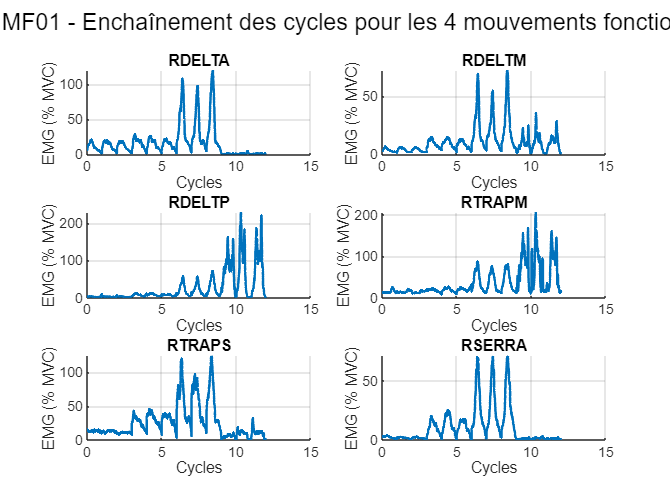


% Création d'une figure pour l'enchaînement des cycles de tous les mouvements fonctionnels
subject_idx = 1;

% Calculer le nombre total de cycles détectés pour tous les mouvements fonctionnels
total_cycles = sum(num_available_cycles_per_functional);

figure;
sgtitle(sprintf('Sujet %s - Enchaînement des cycles pour les 4 mouvements fonctionnels', subjects{1}));

for m = 1:nb_muscles
    subplot(ceil(nb_muscles/2), 2, m);
    hold on;
    
    % Concaténer les données de tous les mouvements fonctionnels et leurs cycles
    all_movements_data = [];
    movement_boundaries = [0]; % Pour stocker où commence chaque mouvement fonctionnel
    cycle_count = 0;
    
    for functional_idx = 1:nb_functional
        functional_data = [];
        
        for cycle = 1:num_available_cycles_per_functional(functional_idx)
            cycle_data = all_functional_data{subject_idx, functional_idx, m, cycle};
 
                % Concaténer les données
                functional_data = [functional_data, cycle_data];
                cycle_count = cycle_count + 1;
        end

        
        % Ajouter une ligne verticale entre les mouvements fonctionnels
        if functional_idx < nb_functional && ~isempty(functional_data)
            all_movements_data = [all_movements_data, functional_data];
            % Stocker la position de fin de ce mouvement fonctionnel
            movement_boundaries = [movement_boundaries, length(all_movements_data)/num_points];
        elseif functional_idx == nb_functional
            all_movements_data = [all_movements_data, functional_data];
        end
    end
    
    % Créer un vecteur de temps pour l'enchaînement complet
    time_concatenated = linspace(0, length(all_movements_data)/num_points, length(all_movements_data));
    
    % Tracer l'enchaînement des cycles
    plot(time_concatenated, all_movements_data, 'LineWidth', 1.5);
    
    title(muscles{m});
    ylabel('EMG (% MVC)');
    xlabel('Cycles');
    grid on;
end


% Création d'une grande matrice pour sauvegarder les données de tous les mouvements fonctionnels
% Format: 6 muscles (lignes) x temps concaténé pour tous les cycles de tous les mouvements (colonnes)
all_data_matrix = zeros(nb_muscles, num_points * total_cycles);

% Remplissage de la matrice
for m = 1:nb_muscles
    col_start = 1;
    
    for functional_idx = 1:nb_functional
        for cycle = 1:num_available_cycles_per_functional(functional_idx)
            cycle_data = all_functional_data{subject_idx, functional_idx, m, cycle};
            
            if ~isempty(cycle_data)
                % Calculer l'indice de fin pour ce cycle
                col_end = col_start + length(cycle_data) - 1;
                
                % S'assurer que nous ne dépassons pas les limites de la matrice
                if col_end <= size(all_data_matrix, 2)
                    all_data_matrix(m, col_start:col_end) = cycle_data;
                else
                    % Ajuster la taille si nécessaire
                    all_data_matrix(m, col_start:size(all_data_matrix, 2)) = cycle_data(1:(size(all_data_matrix, 2)-col_start+1));
                end
                
                % Mettre à jour l'indice de début pour le prochain cycle
                col_start = col_end + 1;
            end
        end
    end
end

% Affichage de la taille de la matrice pour vérification
fprintf('Matrice de données créée avec %d muscles et %d points temporels\n', ...
    size(all_data_matrix, 1), size(all_data_matrix, 2));

Matrice de données créée avec 6 muscles et 12000 points temporels



% Créer un fichier JSON pour stocker les métadonnées des cycles
cycle_metadata = struct();
cycle_count = 0;

for functional_idx = 1:nb_functional
    for cycle = 1:num_available_cycles_per_functional(functional_idx)
        cycle_count = cycle_count + 1;
        field_name = sprintf('cycle_%d', cycle_count);
        cycle_metadata.(field_name) = struct(...
            'functional_idx', functional_idx, ...
            'functional_name', functional_labels{functional_idx}, ...
            'cycle_within_functional', cycle, ...
            'start_point', (cycle_count-1) * num_points + 1, ...
            'end_point', cycle_count * num_points);
    end
end

% Sauvegarde de la matrice et des métadonnées dans un fichier .mat
save_filename = sprintf('%s_all_functionals_data.mat', subjects{1});
save(save_filename, 'all_data_matrix', 'muscles', 'functional_labels', 'cycle_metadata', 'subjects', 'num_available_cycles_per_functional');

fprintf('Données sauvegardées dans le fichier: %s\n', save_filename);

Données sauvegardées dans le fichier: MF01_all_functionals_data.mat



% Optionnel: Création d'une table pour une meilleure visualisation des données
muscle_names = cell(nb_muscles, 1);
for m = 1:nb_muscles
    muscle_names{m} = muscles{m};
end

all_data_table = array2table(all_data_matrix, 'RowNames', muscle_names);

% Création d'un récapitulatif des cycles détectés
fprintf('\nRécapitulatif des cycles détectés:\n');


Récapitulatif des cycles détectés:


fprintf('-----------------------------\n');

-----------------------------


for functional_idx = 1:nb_functional
    fprintf('Mouvement %d - %s: %d cycles\n', ...
        functional_idx, functional_labels{functional_idx}, num_available_cycles_per_functional(functional_idx));
end

Mouvement 1 - Porter les mains à la bouche: 3 cycles
Mouvement 2 - Toucher le haut de la tête: 3 cycles
Mouvement 3 - Porter les mains le plus haut possible au-dessus de la tête: 3 cycles
Mouvement 4 - Porter les mains le plus haut possible le long de la colonne vertébrale: 3 cycles


fprintf('Total: %d cycles\n', total_cycles);

Total: 12 cycles
